# 资产组合的VaR计算 (移动平均法)

本节学习金融风险VaR计算. QTTN_2015_2019.xlsx 是某基金的净值曲线, 本实验计算这个基金的单日最大跌幅.

读取数据.

clear
close all
data = xlsread("QTTN_2015_2019.xlsx");

计算单日对数收益率.

rtn = diff(log(data));

假设股票的收益率是正态分布, 用长度为250的窗口求移动平均.

k = 250;
n = length(rtn);

将收益率处理成滑动窗口扫过的轨迹.

rtn_history = zeros(k, n-k+1);
for i=1:n-k+1
    rtn_history(:, i) = rtn(i:i+k-1);
end

计算滑动平均上每组历史数据的均值和标准差.

VaR = mean(rtn_history) - norminv(0.99)*std(rtn_history);

画出收益率曲线和VaR曲线.

收益率曲线从第1日至1180日.

VaR曲线的第1个是用1~250日数据预测的, 所以是第250日的最大跌幅;

最后1个是用931~1180日数据预测的, 所以是第1180日的最大跌幅.

VaR曲线从第250日至1180日.

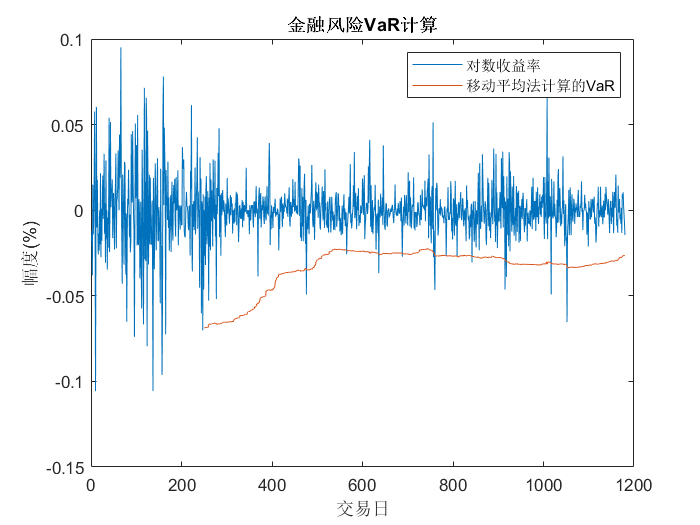

plot(1:n, rtn);
hold on
plot(k:n, VaR);
hold off
legend({'对数收益率', '移动平均法计算的VaR'});
ylabel('幅度(%)');
xlabel('交易日');
title('金融风险VaR计算');

计算超限次数.

exceed = sum(rtn(k:n) < VaR');
fprintf('超限次数: %d\n', exceed);

超限次数: 12
